## Sensor Fusion ENG09040, Course Project:  Vehicle Localisation and Tracking

Student ID: S00241134

Student Name: Senan Stanley

This project records the steps required to produce localisation and tracking results from an eight-node sensor network, from collection to conclusions.

The data gathering was completed in a Virtual laboratory environment, using simulated microphones to gather information on a moving vehicle. The microphone models and data were calibrated to offset bias and two sensor networks were created to model the entire system. The TDOA sensor networks were populated and analysed for optimal design. WLS was used to snapshot localise the network and compare between the two implementations. Further tracking algorithms such as EKF and UKF were implemented to simulate a true live tracking scenario. Results from the models were compared and contrasted with each other to reach a conclusion on the best model for this system. 

## Task 3.0: Data Gathering

The first task of this project was to gather the data from the virtual laboratory environment.

In the calibration mode all microphones were placed an equidistance from the vehicle. which remained stationary and produced a sequence of orthogonal frequency-division multiplexing (OFDM) signals. In this phase data was gathered in order to inform on the bias of each microphone in the network.

In the next phase the microphones were distributed around the track map randomly, but not too close to each other as to render any single microphone redundant. The vehicle drove around the track for a lap and a half, the microphone data and sampling times were recorded.

Each of the calibration measurements and true measurements were processed using the provided $\mathrm{FindPulseTimes}\left(\right)$ function, which converted the signal data into received pulse times for each microphone.

The microphone's cartesian coordinates were:


$$\left\lbrack \begin{array}{ccccccccc}
\mathrm{mic}\;# & 1 & 2 & 3 & 4 & 5 & 6 & 7 & 8\\
x & -33 & 23 & 69 & 68 & -28 & 17 & -66 & -71\\
y & 44 & 42 & 19 & -20 & -49 & -47 & 17 & -18
\end{array}\right\rbrack$$


## Task 3.1: Calibration step

**All 8 microphones must now be calibrated to find their relative bias and the error present in each.**

The sensor model with time measurement is set up as:  


$$ y_i(k) = t_0 + (k-1)*I + t + b_i + e_i$$


Where $i$ denotes the $i^{\mathrm{th}}$ sensor, and $k$ denotes the $k^{\mathrm{th}}$ measurement. $t_0$ is the time when the first signal is sent, $I$ denotes the time interval between two pulses. $t$ is the time duration of the pulse (pulse width), $b_i$ is the bias and $e_i$ is the noise.

First, we use $y_i \left(k\right)-y_i \left(k-1\right)$ to calculate the interval between two pulse transmissions and find the average of those values. 

After this value is known, we can find the mean value of $t_0 +t$ for the first sensor if we assume the bias is 0 for this sensor. 

Next, we calculate the mean pulse interval value for the other sensors without the bias. 

Then we use other sensors' mean value to subtract the first sensor's mean value to get the bias of each sensor corresponding to the first sensor.

% Speed of sound in air
c = 340;  
% Interval between each pulse transmission in seconds
trans_interval=0.5;

% Transpose calibration tphat matrix
if size(tphat,1) ~= 8
	tphat = tphat';
end
% Transpose measurement tphat matrix
if size(tpyhat,2) ~= 8
	tpyhat = tpyhat';
end

Determine error of each sensor:

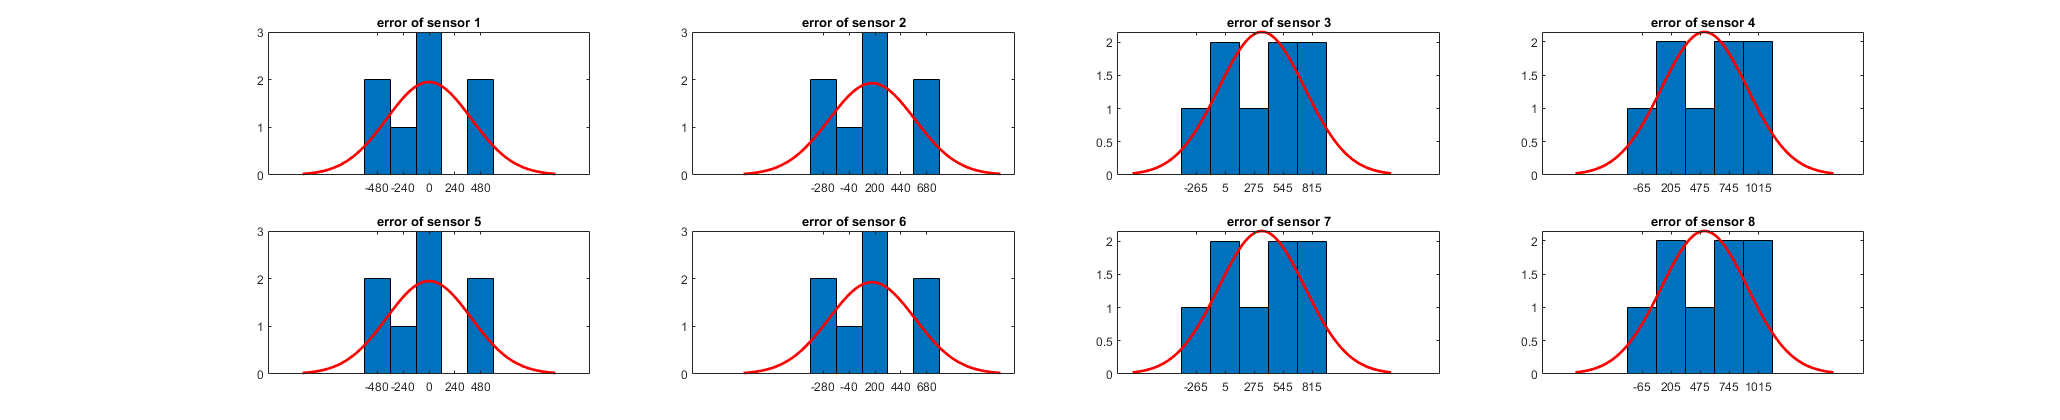

% Get the number of mics and samples
[Nmic, Nsample] = size(tphat); 

% Get the calibration error and measurement error and estimates
[calib_error, ] = compute_mic_error(tphat,trans_interval,c, false);
[meas_error, meas_range_est] = compute_mic_error(tpyhat,trans_interval,c, true); 

In this model, we assume that the first sensor has zero bias, this is because when we use the pairwise TDOA method with the first sensor as the reference sensor, the bias of this sensor can be cancelled and only the difference between other sensor's bias and the reference sensor's bias is needed. The plots illustrate some information about the bias and covariance of noise for each receiver. 

The sensor noise distributions for the measurements shown above do not represent a normal distribution, despite the reference curve applied by the $\mathrm{histfit}\left(\right)$ algorithm.

Perhaps this is a symptom of not collecting enough data to form a normal distribution. Though the bias of each sensor seems quite close to the chosen bias of sensor 1.

% Compute microphone bias and covariance of range measurement (m)
[mic_bias, mic_var] = compute_mic_bias(calib_error);

The microphone biases are calculated relative to the bias of sensor 1.

## Task 3.2: Sensor modelling

This sensor configuration is what's known as a Time Difference Of Arrival (TDOA) sensor network the arrival time of the measurement is known - but the broadcast time is not.

The time of arrival can be modelled as being proportional to the range (between the sensor and a target) plus some sensor bias.


$$\mathrm{TDOA}\;h_k \left(x\right)=r_k =\left\|x-p_k \right\|+r_0$$


The first sensor network model created is a 2D 8 Sensor TDOA with a bias state:


$$\left\|p_t \left(\;n\right)-p_s \left(m\right)\right\|+x\left({\mathrm{Nn}}_x +1\right)$$


% reshape mic locations into a single row vector
th = reshape(miclocations,1,[]);
% Add a null state to x0, for TDOA with bias state
x0_bias = [x0' 0];
% Matrix noise sensor covariance, for TDOA with bias state
R_bias = diag(mic_var);

% 8 Sensor TDOA with range offset state
s_tdoa1 = exsensor('tdoa1',8,1)

s_tdoa1 = SENSORMOD object: TDOA1 with range offset state
       / sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) + x(3,:)   \    
       | sqrt((x(1,:)-th(3)).^2+(x(2,:)-th(4)).^2) + x(3,:)   |    
       | sqrt((x(1,:)-th(5)).^2+(x(2,:)-th(6)).^2) + x(3,:)   |    
       | sqrt((x(1,:)-th(7)).^2+(x(2,:)-th(8)).^2) + x(3,:)   |    
   y = | sqrt((x(1,:)-th(9)).^2+(x(2,:)-th(10)).^2) + x(3,:)  | + e
       | sqrt((x(1,:)-th(11)).^2+(x(2,:)-th(12)).^2) + x(3,:) |    
       | sqrt((x(1,:)-th(13)).^2+(x(2,:)-th(14)).^2) + x(3,:) |    
       \ sqrt((x(1,:)-th(15)).^2+(x(2,:)-th(16)).^2) + x(3,:) /    
   x0'  = [0.94,0.96,0.58]  
   th'  = [0.06,0.23,0.35,0.82,0.015,0.043,0.17,0.65,0.73,0.65,0.45,0.55,0.3,0.74,0.19,0.69]
  States:  x1     x2     x3     
  Outputs: y1     y2     y3     y4     y5     y6     y7     y8     

% Assign TDOA sensor network inputs
s_tdoa1.th = th;
s_tdoa1.x0 = x0_bias;
s_tdoa1.pe = R_bias;

The second sensor network model created is a 2D, 8 Sensor TDOA with pairwise differences:


$$\left\|p_t \left(\;n\right)-p_s \left(m\right)\right\|+\left\|p_t \left(\;k\right)-p_s \left(m\right)\right\|$$


This pairwise network intends to utilise the differences in measurement arrival times to compute the differences in distance, between the paired sensors and the target.

% 8 Sensor TDOA with pairwise differences
s_tdoa2 = exsensor('tdoa2',8,1)

s_tdoa2 = SENSORMOD object: TDOA2 with pairwise differences
       / sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(3)).^2+(x(2,:)-th(4)).^2)     \
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(5)).^2+(x(2,:)-th(6)).^2)     |
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(7)).^2+(x(2,:)-th(8)).^2)     |
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(9)).^2+(x(2,:)-th(10)).^2)    |
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(11)).^2+(x(2,:)-th(12)).^2)   |
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(13)).^2+(x(2,:)-th(14)).^2)   |
       | sqrt((x(1,:)-th(1)).^2+(x(2,:)-th(2)).^2) - sqrt((x(1,:)-th(15)).^2+(x(2,:)-th(16)).^2)   |
       | sqrt((x(1,:)-th(3)).^2+(x(2,:)-th(4)).^2) - sqrt((x(1,:)-th(5)).^2+(x(2,:)-th(6)).^2)     |
       | sqrt((x(1,:)-th(3)).^2+(x(2,:)-th(4)).^2) - sqrt((x(1,:)-th(7)).^2+(x(2,:)-th(8)).^2)     |
       | sqrt((x(1,:)-th(3)).^2


% Matrix of pairwise differences of noise sensor covariance, for TDOA as range differences
var_range = get_pairwise_diff_covar(s_tdoa2.nn(3), Nmic, mic_var);

% Assign TDOA sensor network inputs
s_tdoa2.th = th;
s_tdoa2.x0 = x0';
s_tdoa2.pe = diag(var_range);

## Task 3.3: Experiments

The microphones are set up to have multiple diverse points of measurement to ensure a robust network, accounting for real world bias and error.

The bias is removed from each measurement, using the relative bias calculated in Task 3.1: Calibration step. The bias of each sensor is directly subtracted from each measurement from that sensor.

The pairwise differences for the measurements and the covariance matrix are calculated in a similar fashion to each other.


$$y_{\mathrm{tdoa}} =\left\lbrack \begin{array}{cccc}
y_{1,1} -y_{1,2}  & y_{1,1} -y_{1,3}  & \cdots  & y_{1,n-1} -y_{1,n} \\
y_{2,1} -y_{2,2}  & y_{2,1} -y_{2,3}  & \cdots  & y_{2,n-1} -y_{2,n} \\
\vdots  & \vdots  & \ddots  & \ddots \\
y_{m,1} -y_{m,2}  & y_{m,1} -y_{m,3}  & \ddots  & y_{m,n-1} -y_{m,n} 
\end{array}\right\rbrack$$


Where $y_{\mathrm{tdoa}}$  is the pairwise difference measurements or variance, $y$ is the original measurement or variance, m is the number of measurements or variance & n of sensors.

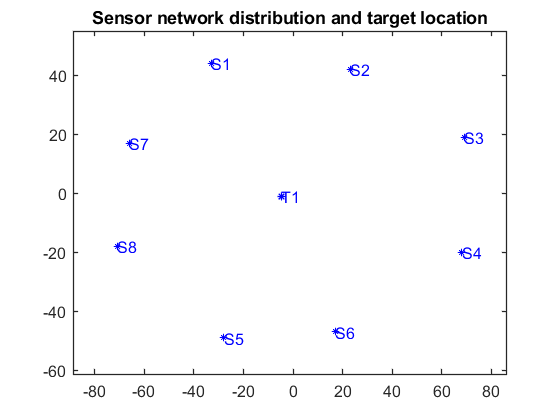

% Remove bias from the measurements
unbiased_range_est = remove_meas_bias(meas_range_est, mic_bias);

% Get the pairwise differences of detection times
meas_range_diff = get_pairwise_diff_meas(unbiased_range_est, s_tdoa2.nn(3), Nmic);

% Create signals for each TDOA network, based on measurement estimates
tdoa1_sig = sig(meas_range_est,2);
tdoa2_sig = sig(meas_range_diff,2);

figure;
plot(s_tdoa1)
title("Sensor network distribution and target location")

The above graphic is a representation of the sensor network (S1-S8) around the starting point of the target (T1).

## Task 3.4: Configuration analysis

***Layout configuration is analysed for the CRLB.***

The Cramer-Rao Lower Bound (CRLB) is a method of getting the lower bound for the variance of an unbiased estimator.


$$\mathrm{Cov}\left(\hat{x} \right)\ge {I^{-1} }_{1:N} \left(x^0 \right)$$
 

The value of the CRLB gives the user the minimum variance that can be expected when using that estimator - the lower the better.

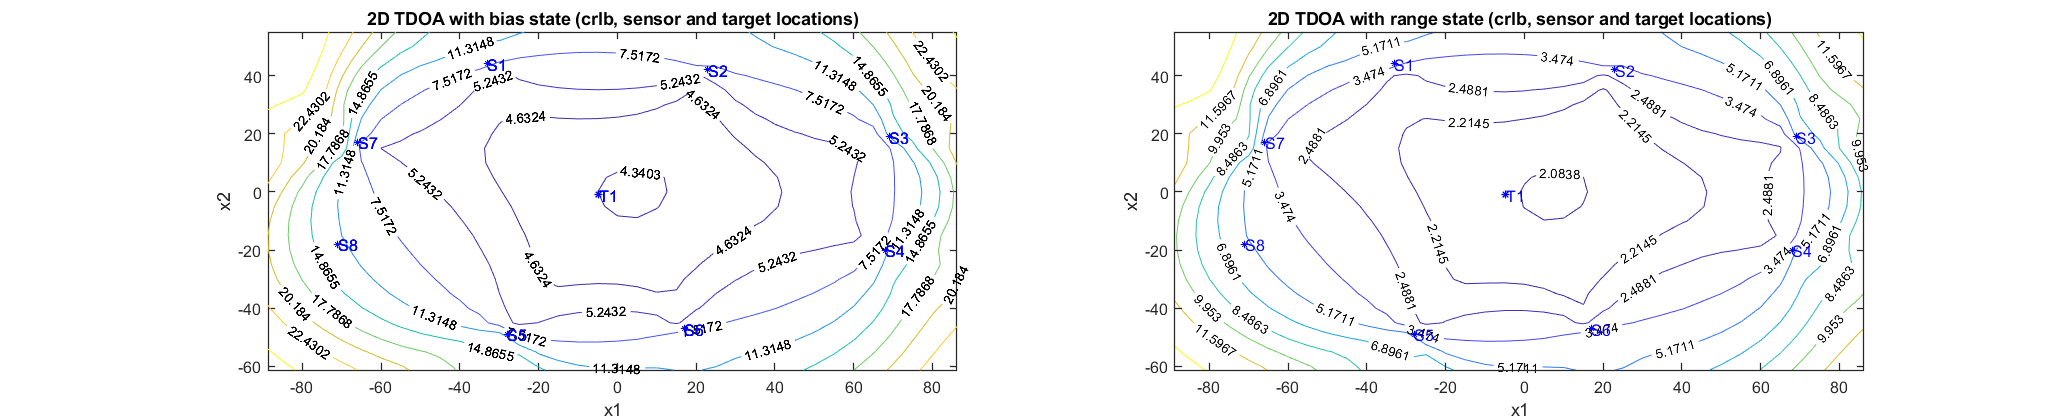

index = [-90:5:90];
subplot(1,2,1)
hold on;
crlb2(s_tdoa1,[],index,index);
plot(s_tdoa1)
title("2D TDOA with bias state (crlb, sensor and target locations)");

subplot(1,2,2)
crlb2(s_tdoa2,[],index,index);
plot(s_tdoa2)
title("2D TDOA with range state (crlb, sensor and target locations)");
hold off;

As can be seen above, the contour plot of the CRLB was computed for each sensor network, TDOA with bias state & TDOA with range state.

The CRLB value for TDOA network with range state is lower at all points than in the the TDOA with bias state. This would imply a lower bound for variance for the former - thus less possible variance for TDOA with range state.

## Task 3.5: Localization

The microphone data measured from the virtual lab was 'snapshot' localised first, comparing TDOA with bias state & TDOA with range state networks.

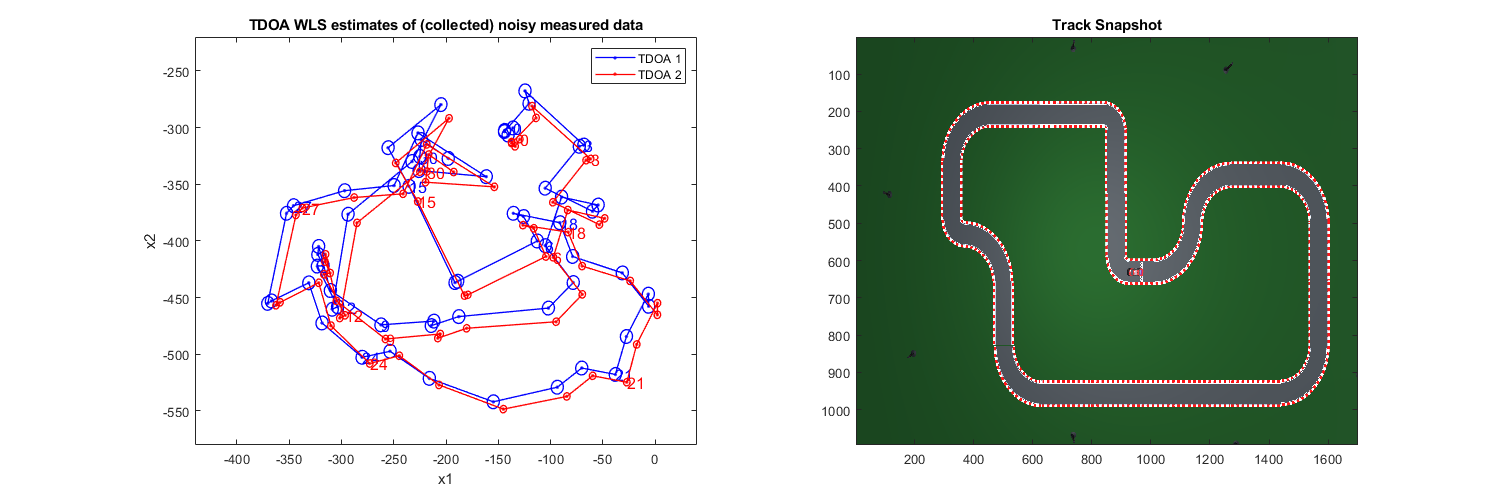

%Testing the measured data using WLS
[xhat1,shat1] = wls(s_tdoa1, tdoa1_sig);
[xhat2,shat2] = wls(s_tdoa2, tdoa2_sig);
% Plot of the TDOA1 % TDOA2 WLS results vs the true track
plot_wls_vs_track(xhat1, xhat2);

As can be seen from the graphs above the original data was unsuitable to be used to localise and track the movement of a vehicle through the network. When compared to the shape of the "true" track on the right deviations can be seen in both sensor networks.

This is due to random "jumps" in the measured data, where microphones would skip readings, only to re-align themselves several readings later.

These errors accumulated and caused the loss in fidelity which can be seen above.

To attenuate this issue generated data was introduced to simulate measurements the microphone sensor network.

A snapshot localisation for weighted least squares (WLS) approach:


$$\mathrm{xhat}={\hat{x} }^{\mathrm{WLS}} =\mathrm{arg}\;\mathrm{min}\left({\left(y-\mathrm{Hx}\right)}^T R^{-1} \left(y-\mathrm{Hx}\right)\right)$$


WLS is a linear regression model, used here to estimate a location value based on the microphone measurements and a sensor network model.

% generate noisy range data for these sections
gen_sig = sig(gen_y,2);

% Calculate the WLS for TDOA network 1
xhat_wls1 = wls(s_tdoa1, gen_sig)

xhat_wls1 = SIG object with continuous time stochastic state space data (no input)
  Sizes:       N = 74,  ny = 8, nx = 3
  MC is set to: 30
  #MC samples:  0

% Plot the setup WLS for TDOA 1. 
subplot(1,2,1)
xplot2(xhat_wls1,'conf',90);
hold on;
plot(s_tdoa1);
t1 = title("WLS TDOA1 snapshot localisation, with 90% confidence");
set(t1,'position',[0 64 0])
hold off;
camroll(-180);

% Calculate the pariwise differences of the generated data
gen_pair = get_pairwise_diff_meas(gen_y, s_tdoa2.nn(3), Nmic);
gen_pair_sig = sig(gen_pair,2);

% Calculate the WLS for TDOA network 2
xhat_wls2 = wls(s_tdoa2,gen_pair_sig)

xhat_wls2 = SIG object with continuous time stochastic state space data (no input)
  Sizes:       N = 74,  ny = 28, nx = 2
  MC is set to: 30
  #MC samples:  0

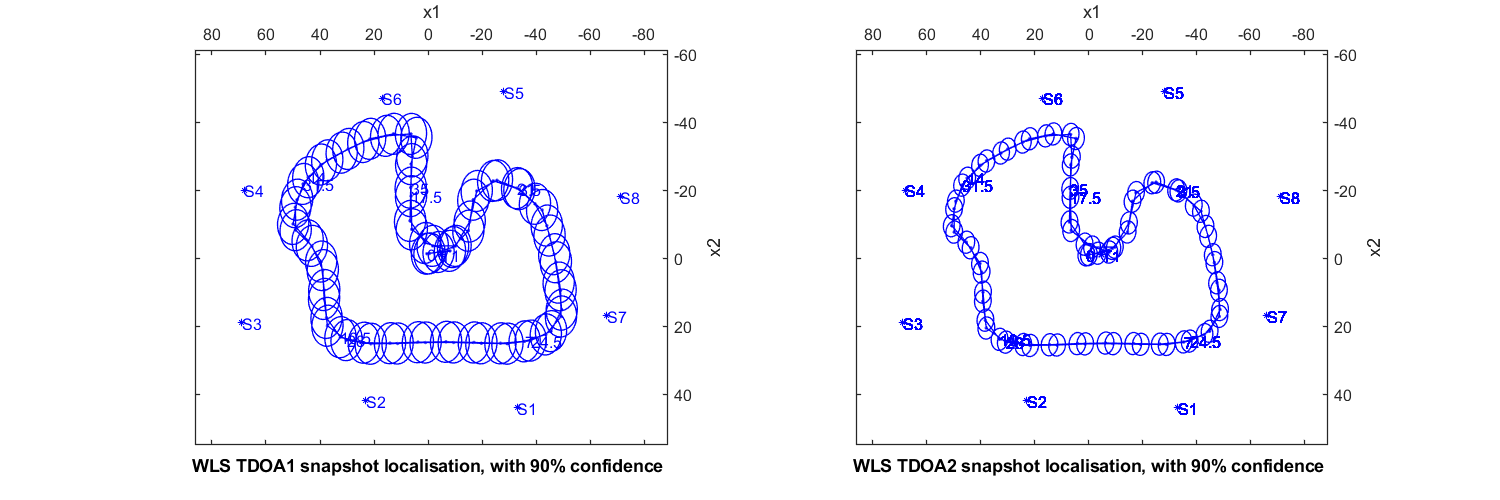

% Plot the setup WLS for TDOA 2. 
subplot(1,2,2)
hold on;
xplot2(xhat_wls2,'conf', 90)
plot(s_tdoa2);
set(gcf, 'Position',[100 100 1500 500])
t2 = title("WLS TDOA2 snapshot localisation, with 90% confidence");
set(t2,'position',[0 64 0])
hold off;
camroll(-180);

As can be seen above the confidence boundaries for the TDOA network 2 (with range state) are smaller than for the TDOA network 1 (with bias state).

This would imply that the TDOA network 2 is more confident of the position of the target at each timestep.

In general, the WLS estimator for the snapshot localisation worked remarkably well. Tracking the true progress of the vehicle to high degree.

**Sidenote:** I struggled immensely to get another NL model working for snapshot localisation. I've been attempting this for the last week now, trying different inputs & syntax to no avail. I asked some of my classmates for help, but they were similarly struggling or busy. This technical issue really marred the end of my project. My apologies, Marion.

## Task 6: Tracking

Create two motion models: Cartesian velocity linear model in 2D (CV2D) & Dead-reckoning of acceleration and yaw rate.

CV2D is a constant velocity model. This model assumed a continuous linear velocity over time, it is a simple motion model.

A dead-reckoning of acceleration and yaw rate motion model assumes an object moves via a combination of linear acceleration and angular velocity.

The models are created and merged with existing sensor networks

%code and explanations for (a) here
mm1 = exmotion('cv2d');
mms1 = addsensor(mm1,s_tdoa1);

mm2 = exmotion('imu2d');
mms2 = addsensor(mm2,s_tdoa2);

Apply the Extended Kalman Filter (EKF) to the models, using the localisation estimates from the last section as measurements.

The EKF is performed in two sections, the Prediction stage:


$${\hat{x\;} }_{k=1|k} =f\left(\hat{x{\;}_{k|k} } \right)$$



$$P_{k=1|k} =f_x^{\prime } \left(\hat{x_{k|k} } \right)P_{k|k} \left(f\prime_x \left(\hat{x_{k|k} } {\left.\right)}^T +f\prime_v \left({\hat{x} }_{k|k} \right)Q_k \left(f\prime_x \left({\hat{x} }_{k|k} \right){\left.\right)}^T \right.\right.\right.$$


And the Update stage: The Innovation covariance is calculated, the optimal Kalman gain is computed, the Corrected estimation is updated & the Covariance is updated.


$$\begin{array}{l}
S_k =h\prime_x \left({\hat{x} }_{k|k-1} \right)P_{k|k} \left(h\prime_x \left({\hat{x} }_{k|k-1} \right){\left.\right)}^T +h\prime_e \left({\hat{x} }_{k|k-1} \right)R_k \left(h\prime_e \left({\hat{x} }_{k|k-1} \right){\left.\right)}^T \right.\right.\\
K_k =P_{k|k-1} \left(h\prime_x \left({\hat{x} }_{k|k-1} \right){\left.\right)}^T S_k^{-1} \right.\\
\varepsilon_k =y_k -h\left({\hat{x} }_{k|k-1} \right)\\
{\hat{x} }_{k|k} ={\hat{x} }_{k|k-1} -1+K_k \varepsilon_k \\
P_{k|k} =P_{k|k-1} -P_{k|k-1} \left(h\prime_x \left({\hat{x} }_{k|k-1} \right){\left.\right)}^T S_k^{-1} h\prime_{\mathrm{xx}} \left({\hat{x} }_{k|k-1} \right)P_{k|k-1} \right.
\end{array}$$


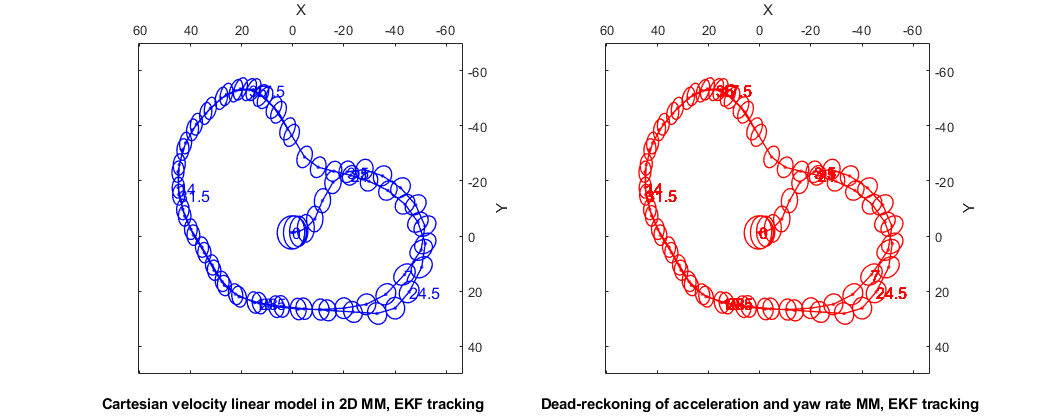

xhat_ekf1 = ekf(mms1,xhat_wls1);
xhat_ekf2 = ekf(mms1,xhat_wls1);
plot_ekf_mod1_v_mod2(xhat_ekf1, xhat_ekf2);

As can be seen above, both models performed similarly when using the EKF for tracking.

The EKFs live tracking of the target's movement approximated the actual movement, but not particularly well. The WLS snapshot localisation obviously outperformed this method of live tracking.

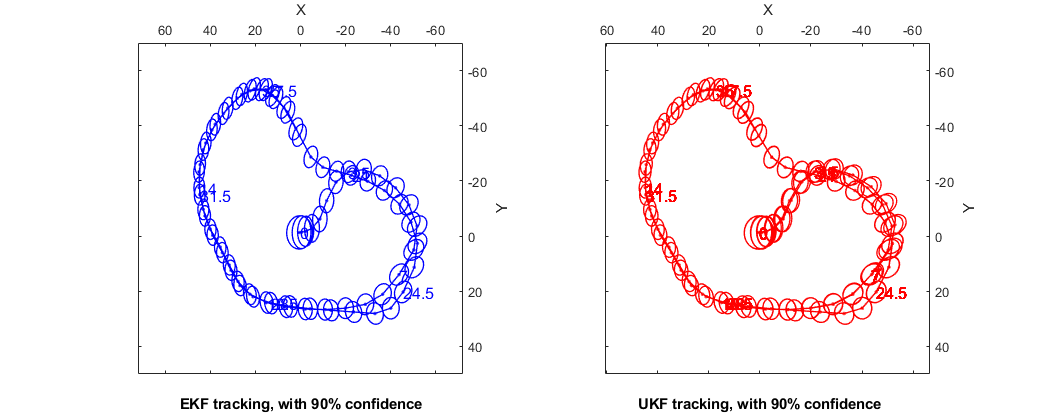

% EKF, UKF & PF 
m1 = nl(mms1);
xhat_ekf1=ekf(m1,xhat_wls1);
xhat_ukf1=ukf(m1,xhat_wls1);
% xhat_pf1=pf(m1,xhat_wls2,'Np',1000);
%Plot EKF, UKF and PF
plot_ekf_ukf(xhat_ekf1, xhat_ukf1);

The EKF and UKF performances were remarkably similar, with the UKF having slightly larger confidence interval - implying a slightly worse performance than the EKF.

## Conclusions

Though a limited number of experiments were carried out with respect to snapshot localisation vs tracking, an obvious conclusion can be drawn. Snapshot localisation is the superior method of target localisation. The errors within a tracking localisation algorithm accumulate and cause the results to devolve the longer the algorithm is deployed. The snapshot has all the information present at once & doesn't deal with the cumulation of error.

The generated data measurements were similarly preferable to the simulated and collected measurements from the Virtual laboratory environment. Were any of these algorithms to be deployed, they would need a far more robust pre-processing and data-collection stage, to ensure the data is as reflective of real-world conditions, as possible.

The bias state and range state TDOA networks obviously differed in their performance. The pairwise difference method of the range state TDOA network performed better overall in this experiment, with lower overall CRLBs as well as the estimators having a higher confidence when computing.

Conversely, the cost of compute times, more calculations and higher complexity, all favour the TDOA bias state network. 

The algorithm, dataset, model, and sensor network representation will always be chosen based on application specific constraints. Though some of these outperformed others in this project, it does not invalidate the use of these other systems, which would be the reasonable choice in another framework.

## Appendix: Lab code

function unbiased_range_est = remove_meas_bias(meas_range_est, mic_bias)
% unbiased_range_est - unbiased range measurements
	unbiased_range_est = zeros(size(meas_range_est));
	for i = 1:size(meas_range_est,1)
		unbiased_range_est(i,:) = meas_range_est(i,:) - mic_bias';
	end
end

function meas_range_diff = get_pairwise_diff_meas(unbiased_range_est, num_diffs, Nmic)
% meas_range_diff - The pairwise differences between sensor measurements
	meas_range_diff = zeros(size(unbiased_range_est,1), num_diffs);
	k = 1;
	for i =[1:Nmic]
		for j = [i+1:Nmic]
			meas_range_diff(:,k) = unbiased_range_est(:,i)-unbiased_range_est(:,j);
			k= k+1;
		end
	end
end

function var_range = get_pairwise_diff_covar(num_diffs, Nmic, mic_var)
% var_range - The pairwise differences between microphone variances
	var_range = zeros(num_diffs,1);
	k = 1;
	for i =[1:Nmic]
		for j = [i+1:Nmic]
			var_range(k) = mic_var(i) + mic_var(j);
			k= k+1;
		end
	end
end

function plot_ekf_ukf(xhat_ekf1, xhat_ukf1)
	hold on;
	subplot(1,2,1);
	xplot2(xhat_ekf1,'conf',90);
	t1 = title("EKF tracking, with 90% confidence");
	set(t1,'position',[0 64 0]);
	camroll(-180);
	subplot(1,2,2);
	xplot2(xhat_ukf1,'conf',90,'col','r');
	t2 = title("UKF tracking, with 90% confidence");
	set(t2,'position',[0 64 0]);
	camroll(-180);
end

function plot_ekf_mod1_v_mod2(xhat_ekf1, xhat_ekf2)
	hold on;
	subplot(1,2,1);
	xplot2(xhat_ekf1,'conf',90);
	t1 = title("Cartesian velocity linear model in 2D MM, EKF tracking");
	set(t1,'position',[0 64 0]);
	camroll(-180);
	subplot(1,2,2);
	xplot2(xhat_ekf2,'conf',90,'col','r');
	t2 = title("Dead-reckoning of acceleration and yaw rate MM, EKF tracking");
	set(t2,'position',[0 64 0]);
	camroll(-180);
end

function plot_wls_vs_track(xhat1, xhat2)
	subplot(1,2,1)
	p1 = xplot2(xhat1,'conf',90);
	hold on;
	p2 = xplot2(xhat2,'conf',90, 'col', 'r');
	legend([p1,p2],{'TDOA 1','TDOA 2'});
	% plot(s_tdoa1);
	title("TDOA WLS estimates of (collected) noisy measured data");
	hold off;
	subplot(1,2,2)
	img = imread('TrackMap.png');
	image(img);
	title("Track Snapshot");
end

### Provided Functions

function [mic_error, range_est] = compute_mic_error(tphat, trans_interval, c, graph)
% mic_error - the computed error (m) of the range estimated from the microphone pulse toa. First we
% subtract the intervals between each pulse transmission 
    [size_row, size_col] = size(tphat);
    for i = 1:size_col
        interval(1:size_row,i) = trans_interval * (i-1);
    end
    toa_est = tphat - interval; % Time of arrival of each individual pulse including bias due to unknown pulse transmission time
    range_est=toa_est*c; %Range estimate at each pulse including bias due to unknown pulse transmission time
    
    % we assign the first sensor has 0 bias, and define the bias of the
    % other sensors relative to the first sensor

    true_first_meas = mean(toa_est(1,:)); %% the mean value of the first sensor toa including unknown transmission time (t + trans), is we assume
    %the bias is 0
 
    true_meas = interval + true_first_meas; %% expected 'true' value of each pulse time assuming zero bias from sensor 1

    error_meas = tphat - true_meas; %% this is bias_i - bias_1 + e_i -e_1
    mic_error = error_meas*c;
	
	if (graph == true)
	    figure;
		title("Sensor Error Histograms")
	    subplot(2,4,1)
	    histfit(mic_error(1,:),5)
	    title('error of sensor 1')
	    subplot(2,4,2)
	    histfit(mic_error(2,:),5)
	    title('error of sensor 2')
	    subplot(2,4,3)
	    histfit(mic_error(3,:),5)
	    title('error of sensor 3')
	    subplot(2,4,4)
	    histfit(mic_error(4,:),5)
	    title('error of sensor 4')
	    subplot(2,4,5)
	    histfit(mic_error(1,:),5)
	    title('error of sensor 5')
	    subplot(2,4,6)
	    histfit(mic_error(2,:),5)
	    title('error of sensor 6')
	    subplot(2,4,7)
	    histfit(mic_error(3,:),5)
	    title('error of sensor 7')
	    subplot(2,4,8)
	    histfit(mic_error(4,:),5)
	    title('error of sensor 8')
		pos = get(gcf, 'Position');
		set(gcf, 'Position',pos+[200 0 1500 0])
	end
end

function [mic_bias, mic_variance] = compute_mic_bias(mic_error)
% mic_bias     - the bias of each microphone
% mic_variance - the error variance of each microphone
%in the current assumption, the first sensor is reference sensor, the bias for this is assumed to be 0
    mic_bias(:,1) = mean(mic_error,2);
    mic_variance(:,1) = var(mic_error,0,2);
end